# DSP Lab - Homework2

#### Mahdi Mahjouri Namin 40023125

#### Nima Nourizadeh 40023086

close all;
clear;
clc;

**Section 1-6**

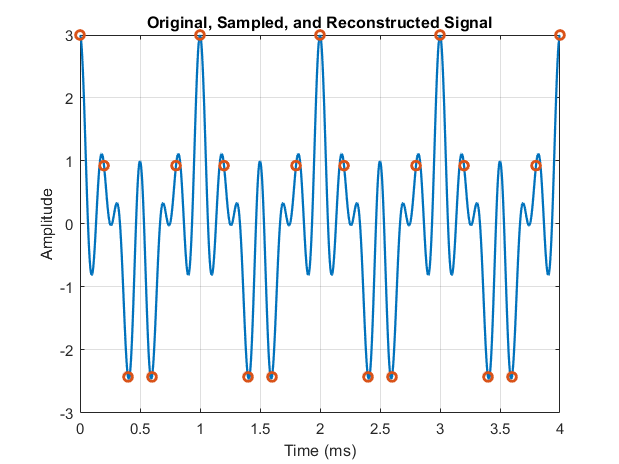

fs_high = 1e6; 
t = 0:1/fs_high:4e-3; 
x = cos(2*pi*1e3*t) + cos(2*pi*4e3*t) + cos(2*pi*6e3*t); 
fs_sample = 5e3;
t_sample = 0:1/fs_sample:4e-3;

x_sample = cos(2*pi*1e3*t_sample) + cos(2*pi*4e3*t_sample) + cos(2*pi*6e3*t_sample);

figure;
plot(t*1000, x,'LineWidth', 1.5); hold on;
plot(t_sample*1000, x_sample, 'o', 'LineWidth', 2);

xlabel('Time (ms)');
ylabel('Amplitude');
title('Original, Sampled, and Reconstructed Signal');
grid on;

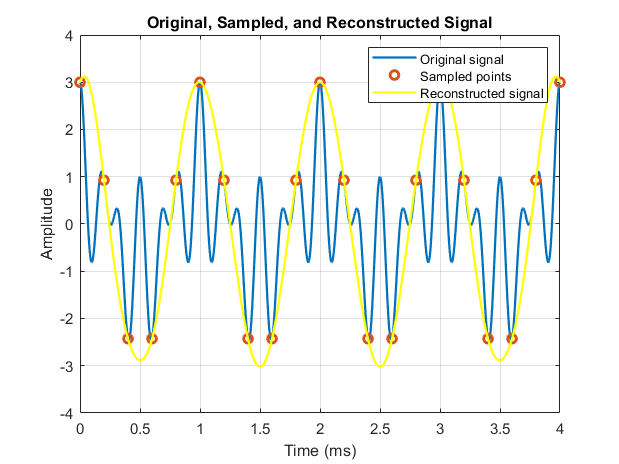

x_recon = zeros(size(t));
for n = 1:length(t_sample)
    x_recon = x_recon + x_sample(n) * sinc(fs_sample*(t - t_sample(n)));
end


plot(t*1000, x_recon,'y', 'LineWidth', 1.5);
legend('Original signal', 'Sampled points', 'Reconstructed signal');

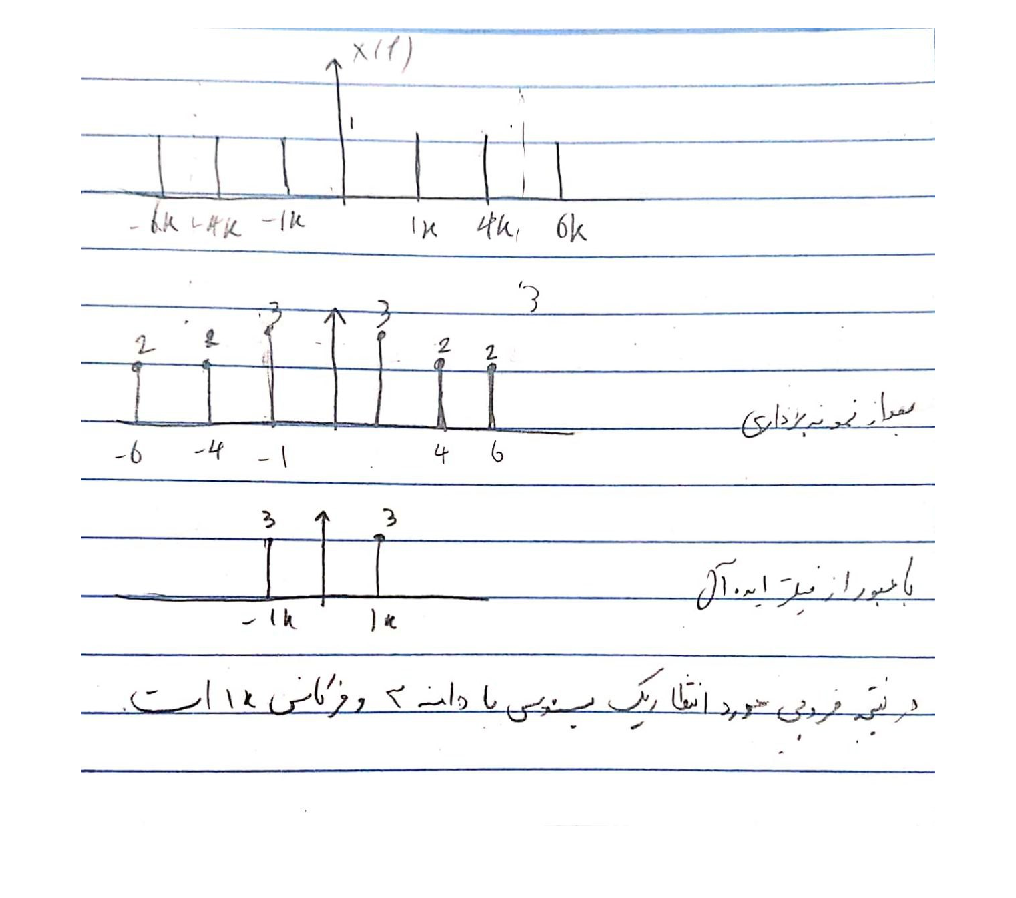

figure
img = imread('1-6.jpg');
imshow(img);

**Section 1-7**

fs = 100; 
t = -5:1/fs:5;
x_t = (sinc(5*t)).^2;


sampling_frequencies = [20, 10, 5, 4];


N = length(x_t);
f_axis = linspace(-50, 50, N);
FT_x = fftshift(fft(x_t))/fs;
sampling_frequencies

sampling_frequencies =     20    10     5     4


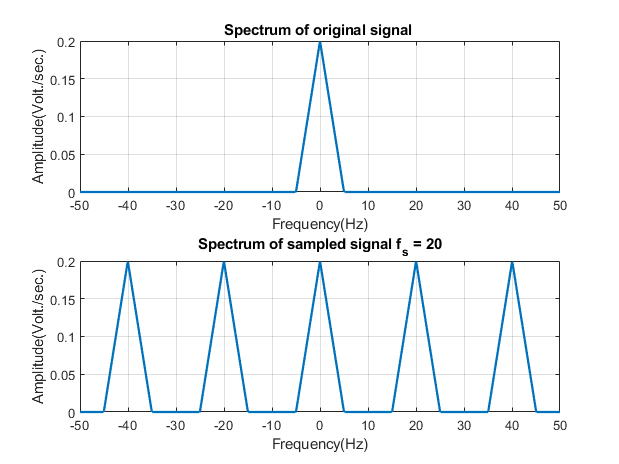

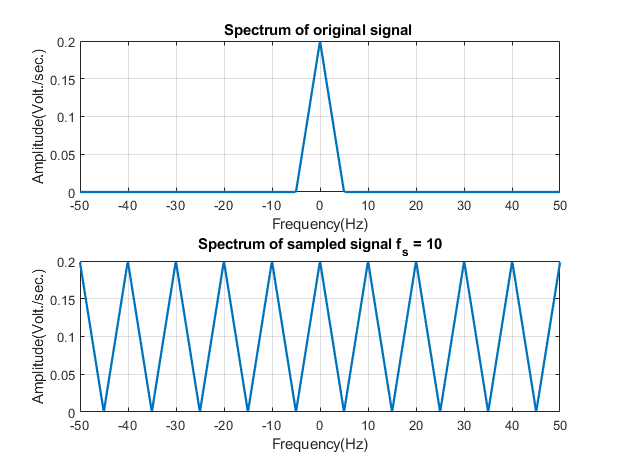

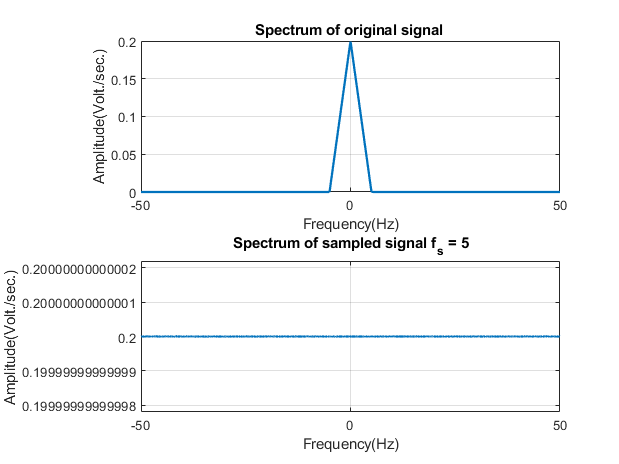

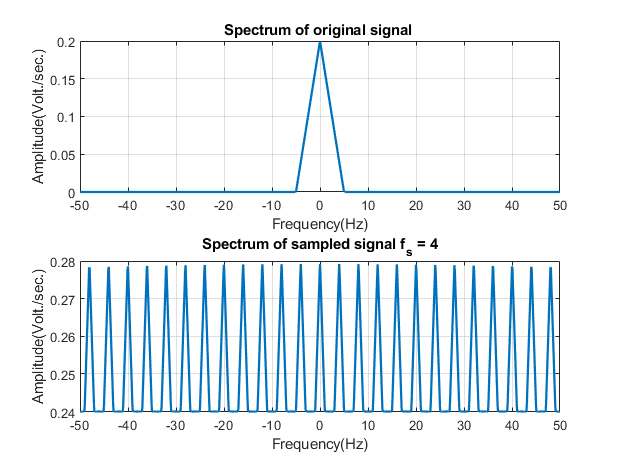

for i = 1:length(sampling_frequencies)
    sampling_frq = sampling_frequencies(i);
    
    sampled_signal = zeros(1, N);
    sampled_signal(1:fs / sampling_frq:end) = x_t(1:fs / sampling_frq:end);
    FT_sampled_signal = 1 / sampling_frq * fftshift(fft(sampled_signal));
    figure('Name', 'Aliasing in frequency domain');
    
    subplot(2, 1, 1);
    plot(f_axis, abs(FT_x), 'LineWidth', 1.5);
    xlabel('Frequency(Hz)');
     ylabel('Amplitude(Volt./sec.)');
     title('Spectrum of original signal ');
     grid on;
     
     subplot(2, 1, 2);
     plot(f_axis, abs(FT_sampled_signal), 'LineWidth', 1.5);
     xlabel('Frequency(Hz)');
     ylabel('Amplitude(Volt./sec.)');
     title(sprintf('Spectrum of sampled signal f_s = %d', sampling_frq));
     
     grid on;
     
end 

**Section 1-8**

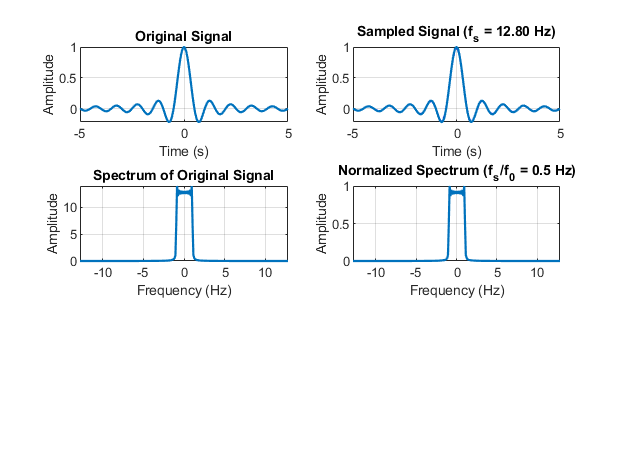

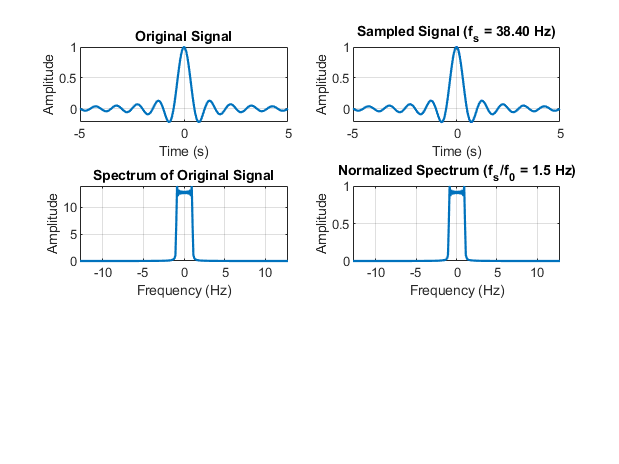

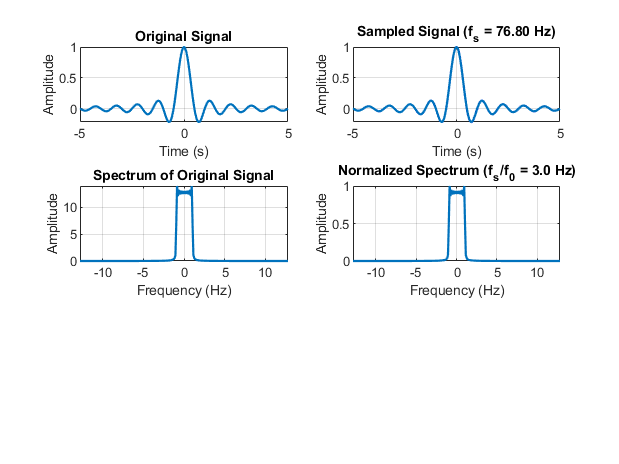

N = 256;                      
t = linspace(-5, 5, N);       
x = sinc(2*t);             

fs = N / 10;                  


fs_ratios = [0.5, 1.5, 3];

for i = 1:length(fs_ratios)
    fs_new = fs * fs_ratios(i);     
    Ts_new = 1 / fs_new;
    t_sampled = -5:Ts_new:5;
    x_sampled = sinc(2*t_sampled);
    
    
    X_f = fftshift(abs(fft(x)));
    X_f = X_f / max(X_f);
    f_axis = linspace(-fs/2, fs/2, N);

    
    N_sampled = length(x_sampled);
    X_sampled_f = fftshift(abs(fft(x_sampled)));
    X_sampled_f = X_sampled_f / max(X_sampled_f);
    f_sampled_axis = linspace(-fs_new/2, fs_new/2, N_sampled);

    
    figure('Name', sprintf('Sampling ratio = %.1f', fs_ratios(i)), 'NumberTitle', 'off');
    
    
    subplot(3,2,1);
    plot(t, x, 'LineWidth', 1.5);
    title('Original Signal');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;

    
    subplot(3,2,2);
    plot(t_sampled, x_sampled, 'b', 'LineWidth', 1.5);
    hold on;
    plot(t, x, 'LineWidth', 1.5);
    title(sprintf('Sampled Signal (f_s = %.2f Hz)', fs_new));
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;

    
    subplot(3,2,3);
    plot(f_axis, abs(fftshift(fft(x))), 'LineWidth', 1.5);
    title('Spectrum of Original Signal');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;

    
    subplot(3,2,4);
    plot(f_axis, X_f, 'LineWidth', 1.5);
    title(sprintf('Normalized Spectrum (f_s/f_0 = %0.1f Hz)', fs_ratios(i)));
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;

    
end

**Section 1-9 (a)**

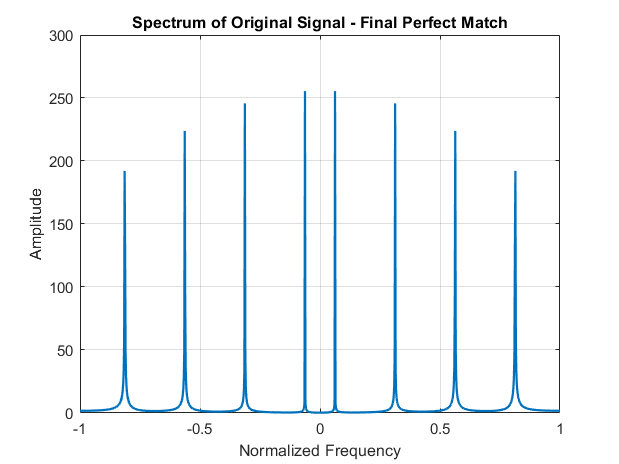

fs = 2;                          
t = -256:1/fs:255;               

x_t = cos(2*pi*(1/16)*t) + ...
      cos(2*pi*(5/16)*t) + ...
      cos(2*pi*(9/16)*t) + ...
      cos(2*pi*(13/16)*t);

N = length(x_t);
X_f = fftshift(fft(x_t));
f_axis_norm = linspace(-1, 1, N);

% رسم
figure;
plot(f_axis_norm, abs(X_f)/2, 'LineWidth', 1.5);
xlabel('Normalized Frequency');
ylabel('Amplitude');
title('Spectrum of Original Signal - Final Perfect Match');
grid on;

**Section 1-9 (b)**

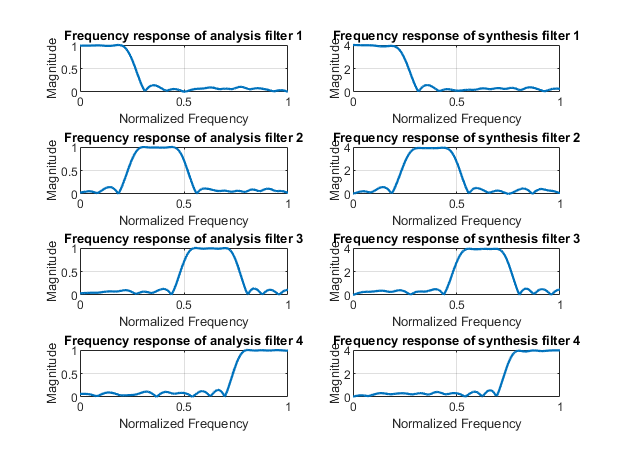

analysis_filters =xlsread('filters.xls', 1);

synthesis_filters = xlsread('filters.xls', 2);
figure('Name', "Amplitiude of frequency response of digital filters");

for i = 1:4
    n = 0:32 - 1;
    w_axis = linspace(0, pi, 1e3);
    kernel = exp(-1j * n' * w_axis);
    H = analysis_filters(i, :) * kernel;
    subplot(4, 2, 2 * i -1);
    plot(w_axis / pi, abs(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
    xlim([0 1]);
    title(strcat("Frequency response of analysis filter ", string(i)));
    grid on;

    H = synthesis_filters(i, :) * kernel;
    subplot(4, 2, 2 * i);
    plot(w_axis / pi, abs(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
    xlim([0 1]);
    title(strcat("Frequency response of synthesis filter ", string(i)));
    grid on;
end

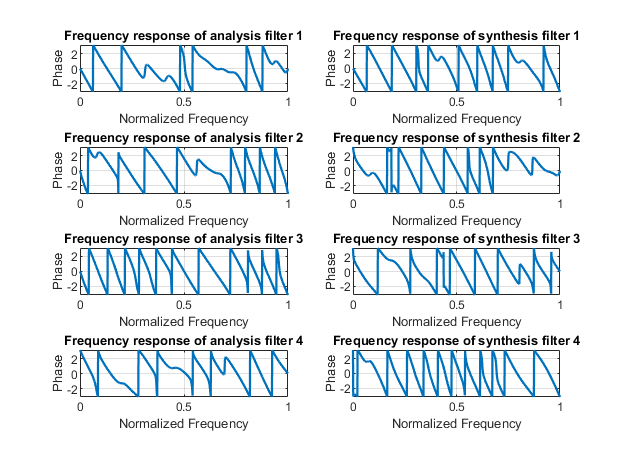

figure('Name', "Phase of frequency response of digital filters");

for i = 1:4
    n = 0:32 - 1;
    w_axis = linspace(0, pi, 1e3);
    kernel = exp(-1j * n' * w_axis);
    H = analysis_filters(i, :) * kernel;
    subplot(4, 2, 2 * i -1);
    plot(w_axis / pi, angle(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Phase');
    xlim([0 1]);
    title(strcat("Frequency response of analysis filter ", string(i)));
    grid on;

    H = synthesis_filters(i, :) * kernel;
    subplot(4, 2, 2 * i);
    plot(w_axis / pi, angle(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Phase');
    xlim([0 1]);
    title(strcat("Frequency response of synthesis filter ", string(i)));
    grid on;

end

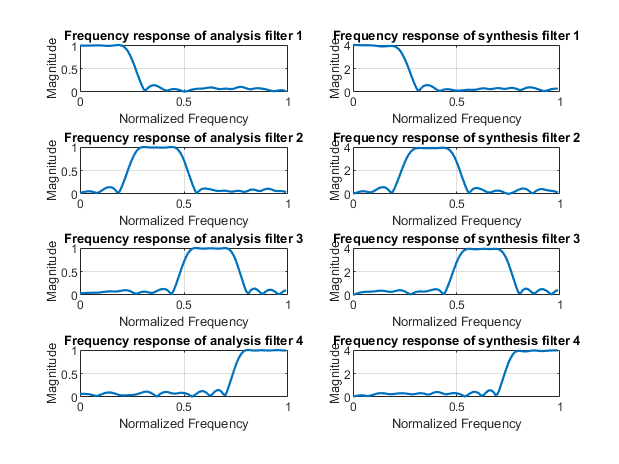

figure('Name', "Amplitiude of frequency response of digital filters");

for i = 1:4
    n = 0:32 - 1;
    [H, w_axis] = freqz(analysis_filters(i, :), 1, 100);
    subplot(4, 2, 2 * i -1);
    plot(w_axis / pi, abs(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
    xlim([0 1]);
    title(strcat("Frequency response of analysis filter ", string(i)));
    grid on;

    [H, w_axis] = freqz(synthesis_filters(i, :), 1, 100);
    subplot(4, 2, 2 * i);
    plot(w_axis / pi, abs(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Magnitude');
    xlim([0 1]);
    title(strcat("Frequency response of synthesis filter ", string(i)));
    grid on;
end

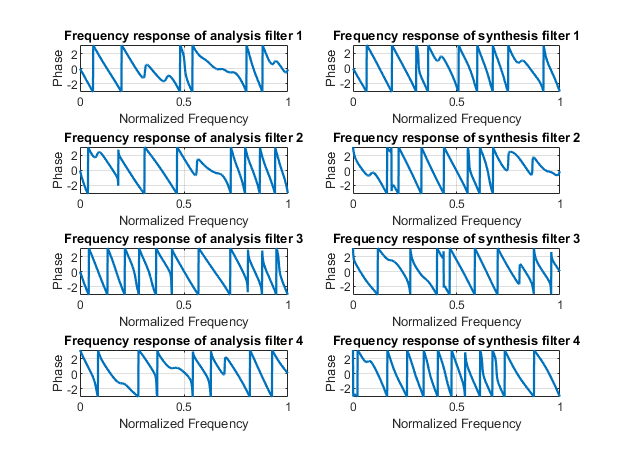

figure('Name', "Phase of frequency response of digital filters");

for i = 1:4
    [H, w_axis] = freqz(analysis_filters(i, :), 1, 1024);
    subplot(4, 2, 2 * i -1);
    plot(w_axis / pi, angle(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Phase');
    xlim([0 1]);
    title(strcat("Frequency response of analysis filter ", string(i)));
    grid on;

    [H, w_axis] = freqz(synthesis_filters(i, :), 1, 1024);
    subplot(4, 2, 2 * i);
    plot(w_axis / pi, angle(H), 'LineWidth', 1.5);
    xlabel('Normalized Frequency');
    ylabel('Phase');
    xlim([0 1]);
    title(strcat("Frequency response of synthesis filter ", string(i)));
    grid on;

end

**Section 1-9 (c)**

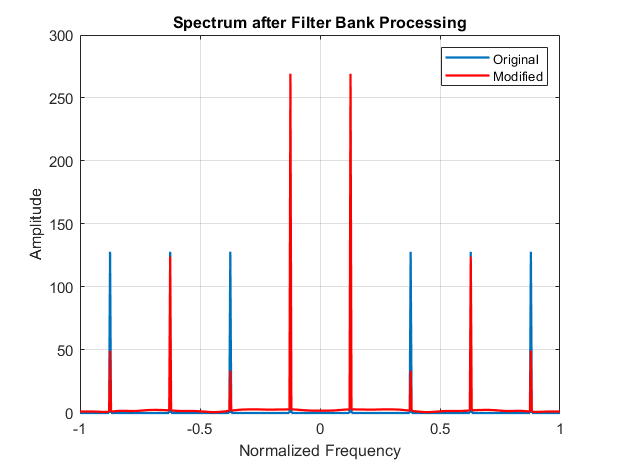

fs = 2;
t = linspace(-256, 255, 512);  

x_t = cos(2*pi*(1/16)*t) + ...
      cos(2*pi*(5/16)*t) + ...
      cos(2*pi*(9/16)*t) + ...
      cos(2*pi*(13/16)*t);


analysis_filters = xlsread('filters.xls', 1);
synthesis_filters = xlsread('filters.xls', 2);

 
N = length(x_t);
L = N / 4;  


x_subbands = zeros(4, L);
for i = 1:4
    filtered = conv(x_t, analysis_filters(i, :), 'same');
    x_subbands(i, :) = downsample(filtered, 4);
end


scaling_factors = [2, 0, 1, 0.5];
for i = 1:4
    x_subbands(i, :) = x_subbands(i, :) * scaling_factors(i);
end


y_t = zeros(1, N);
for i = 1:4
    upsampled = upsample(x_subbands(i, :), 4);
    reconstructed = conv(upsampled, synthesis_filters(i, :), 'same');
    y_t = y_t + reconstructed;
end


X_f = fftshift(fft(x_t));
Y_f = fftshift(fft(y_t));
f_axis_norm = linspace(-1, 1, N);

figure;
plot(f_axis_norm, abs(X_f)/2,  'LineWidth', 1.5); hold on;
plot(f_axis_norm, abs(Y_f)/2, 'r', 'LineWidth', 1.5);
xlabel('Normalized Frequency');
ylabel('Amplitude');
legend('Original', 'Modified');
title('Spectrum after Filter Bank Processing');
grid on;